# Travail 1 :

## A1.

On a $T_n \left(f\right)-R_n \left(f\right)=\frac{10}{n}\times \left(f\left(10\right)-f\left(-10\right)\right)$

## A2.

Si $f$s'annule en dehors de $\left\lbrack -8;8\right\rbrack \;$alors $T_n \left(f\right)-R_n \left(f\right)=0$

## B1.

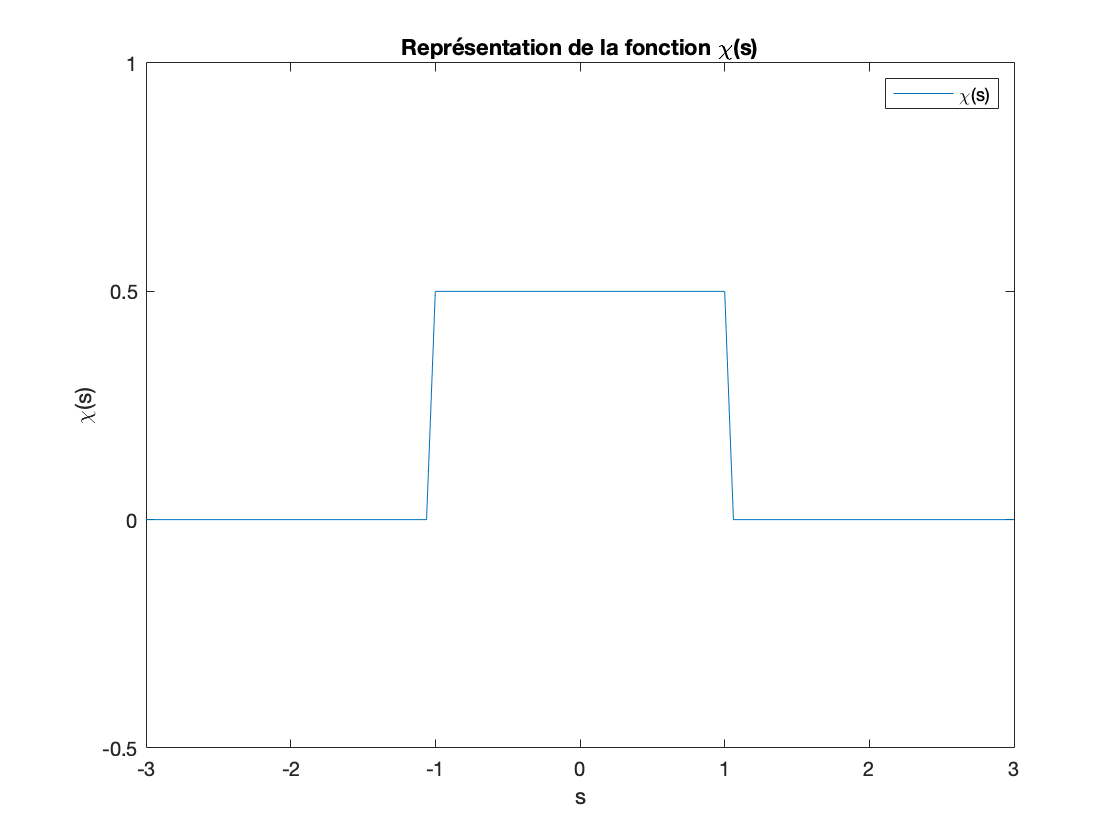

xsi = @(x) (x>=-1).*(x<=1).*0.5;
x = linspace(-3,3,100);
plot(x,xsi(x));
axis([-3 3 -1/2 1])
title("Représentation de la fonction \chi(s)")
legend("\chi(s)")
xlabel("s")
ylabel("\chi(s)")

## B2.

n = [10 50 100];
R = []


R =

     []



T = []


T =

     []



global a
a = -10;
global b 
b = 10;
Rn = @(f,n1) ((b-a)/n1)*sum(f(a+(0:(n1-1))*((b-a)/n1)));
Tn = @(f,n1) ((b-a)/n1)*(((f(a)+f(b))/2) +  sum(f(a+((1:(n1-1))*(b-a)/n1))));
for i=1:(length(n))
    R(i) =Rn(xsi,n(i));
    T(i) =Tn(xsi,n(i));
end
R 

R =     1.0000    1.0000    1.1000


T

T =     1.0000    1.0000    1.1000


## B3.

xsi_conv = @(t,s) xsi((t-s)).*xsi(s);
Rn2 = @(f,t,n1) ((b-a)/n1)* sum(f(t,a+(0:(n1-1))*((b-a)/n1)));
Tn2 = @(f,t,n1) ((b-a)/n1)*(((f(t,a)+f(t,b))/2) +  sum(f(t,a+((1:(n1-1))*(b-a)/n1))));
Ra= []


Ra =

     []



Ta = []


Ta =

     []




for i=1:(length(n))
    T = a+[0:n(i)].*((b-a)/n(i));
    T
    for j=1:length(T)
        Ra(i,j) =Rn2(xsi_conv,T(j),n(i));
        Ta(i,j) =Tn2(xsi_conv,T(j),n(i));
    end
end

T =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


T =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


T =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010



Ta

Ta =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1000    0.1000    0.2000    0.2000    0.3000    0.3000    0.4000    0.4000    

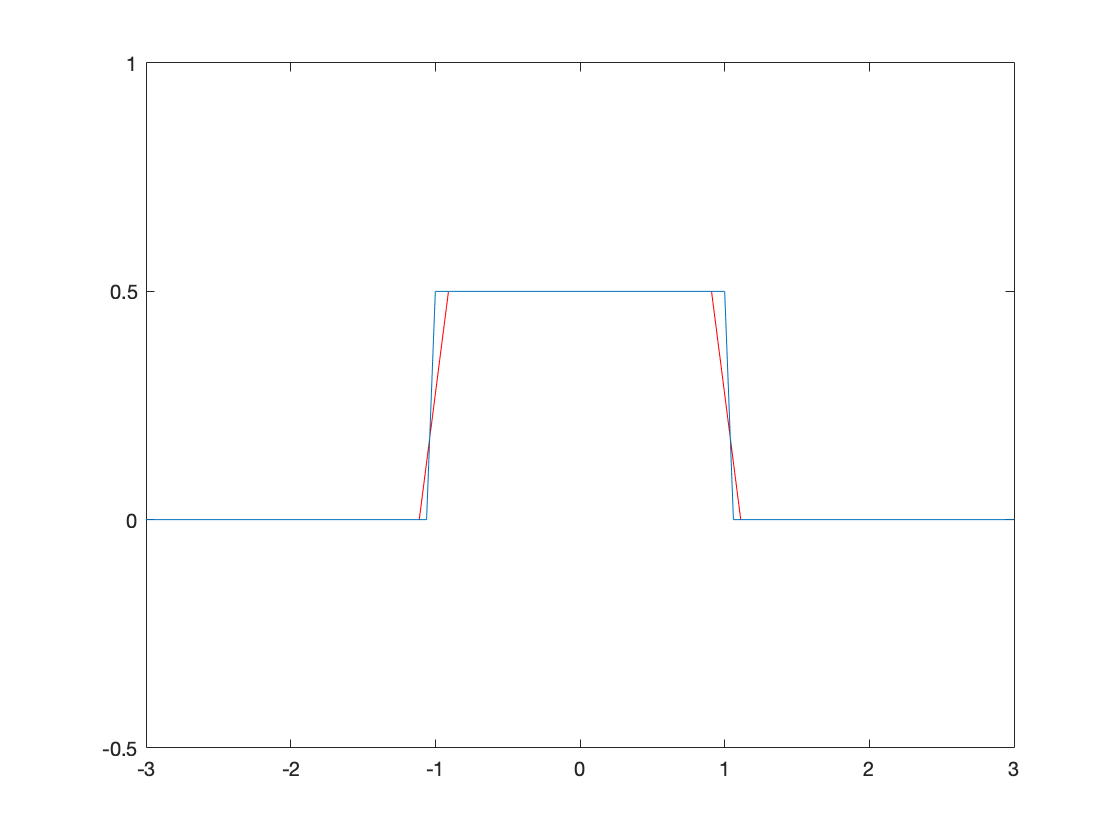

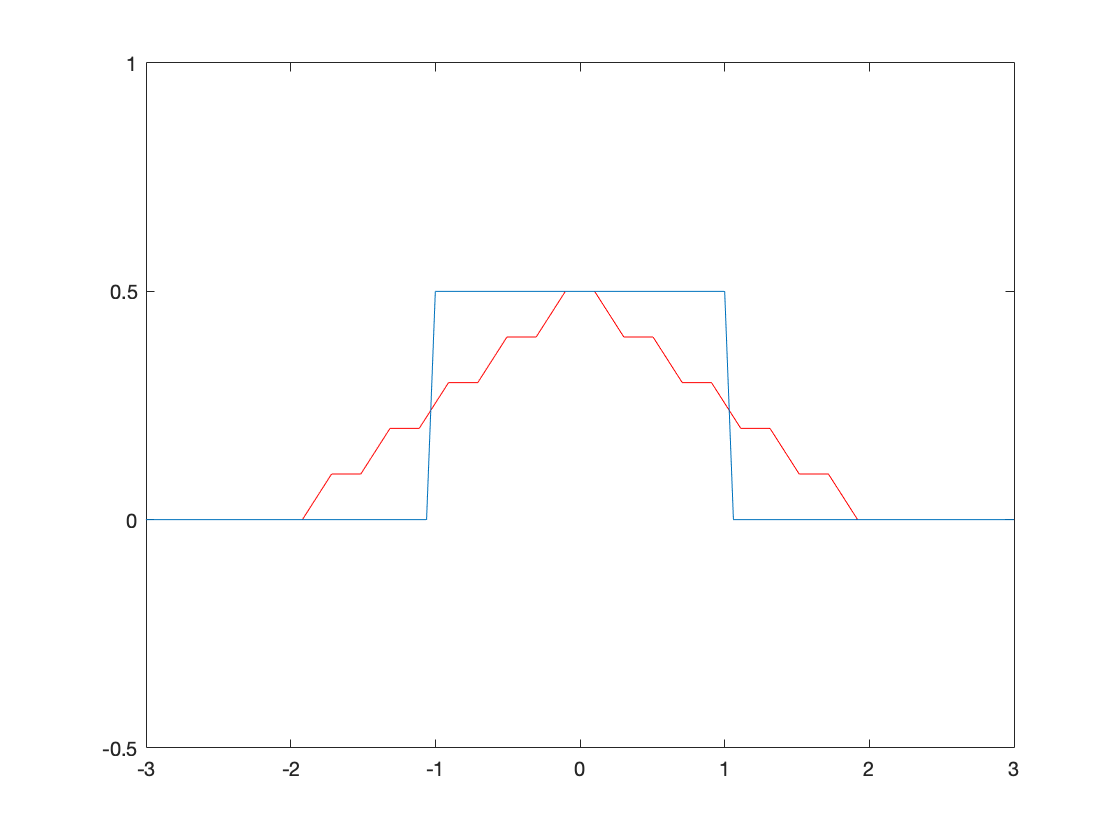

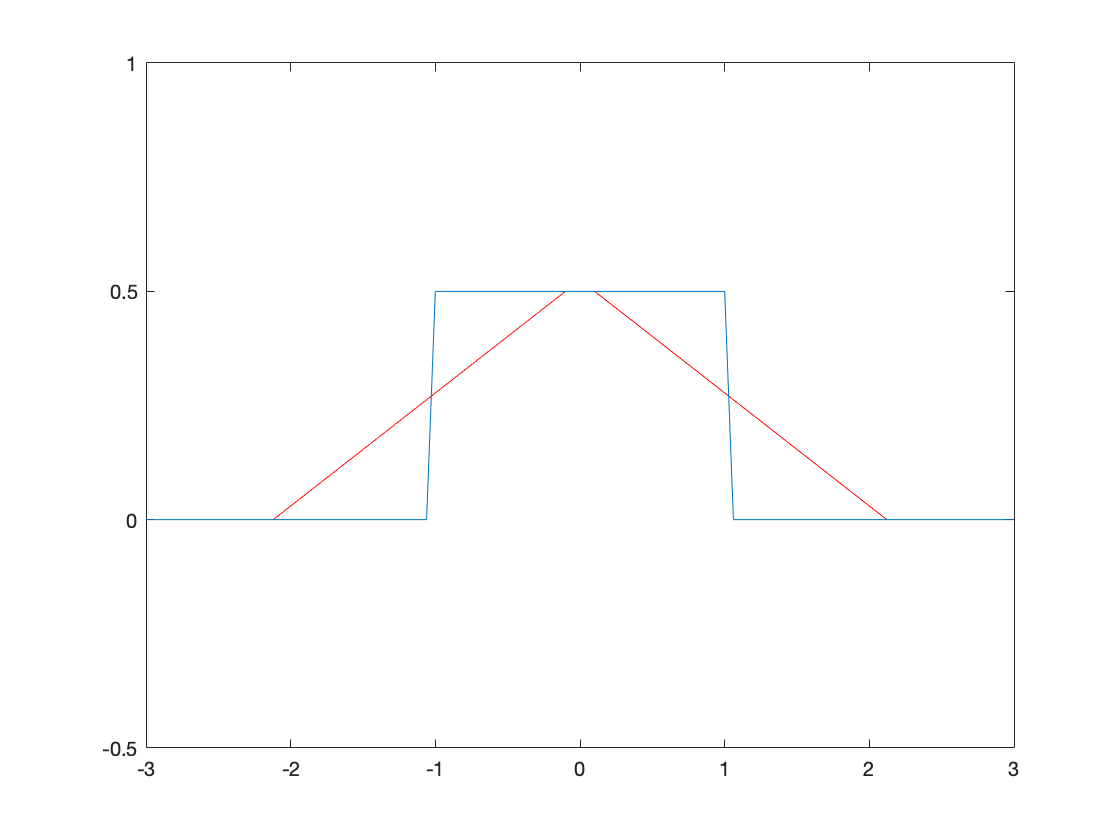

for i=1:3
    figure()
    plot(a+[0:n(i)].*((b-a)/n(i)),Ra(i,1:(n(i)+1)),'Color','red')
    line(x,xsi(x))
    axis([-3 3 -0.5 1])
end

for i=1:3
    figure()
    plot(a+[0:n(i)].*((b-a)/n(i)),Ta(i,1:(n(i)+1)),'Color','red')
    line(x,xsi(x))
    axis([-3 3 -0.5 1])
end